**Project: American Sign Language (ASL) Alphabet Classification**

%% ASLAlphabetClassificationResNet50.m
% Author: Kirubhakaran Meenakshi Sundaram
%
% Project Introduction:
% This project implements a deep learning-based American Sign Language (ASL)
% alphabet classifier using transfer learning with a pre-trained ResNet-50 model.
% The classifier distinguishes between 24 ASL letters (excluding 'J' and 'Z') 
% using a dataset of hand sign images. The workflow covers data loading, preprocessing, 
% model training, evaluation on a test set, and final prediction on new unlabeled images.
%
% Transfer learning leverages the ResNet-50 architecture trained on ImageNet,
% fine-tuned here to learn ASL alphabet features efficiently with limited data.
%
% Dataset:
% The dataset is organized into 'Train', 'Test', and 'Unlabeled' folders, with
% images grouped by class labels. The project performs data augmentation by resizing 
% images to match the network input size and applies standard training routines 
% to maximize accuracy.
%
% The final model is evaluated on a labeled test set, and predictions are generated
% for unlabeled images to demonstrate real-world applicability.


**Part 1: Data Preparation and Exploration**


% Define file paths for datasets
filenameTrain = "Data\Train";
filenameTest = "Data\Test";
filenameUnlabeled = "Data\Unlabeled";

% Load images from folders, label inferred from folder names
imdsTrain = imageDatastore(filenameTrain, "IncludeSubfolders", true, "LabelSource", "foldernames");
imdsTest = imageDatastore(filenameTest, "IncludeSubfolders", true, "LabelSource", "foldernames");
imdsUnlabeled = imageDatastore(filenameUnlabeled, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Split training data into training and validation (80%-20%) sets
[dsTrain, dsVal] = splitEachLabel(imdsTrain, 0.8, "randomized");

% Load a pre-trained ResNet-50 model and modify output for 24 classes
net = imagePretrainedNetwork("resnet50", "NumClasses", 24);
inputSize = net.Layers(1).InputSize;

% Resize images to network input size using data augmentation objects
augTrain = augmentedImageDatastore(inputSize, dsTrain);
augVal = augmentedImageDatastore(inputSize, dsVal);
augTest = augmentedImageDatastore(inputSize, imdsTest);
augUnlabeled = augmentedImageDatastore(inputSize, imdsUnlabeled);

% Display dataset statistics and sample images
disp("Number of test images: " + length(imdsTest.Labels));

Number of test images: 240


countEachLabel(dsVal);  % Show label distribution in validation set
size(imdsTrain.read()); % Display size of an example image

% Optional: Visualize sample images for letters 'A' and 'B'
montage(imdsTest.Files(imdsTest.Labels == 'A'));
title('Sample images of letter A');

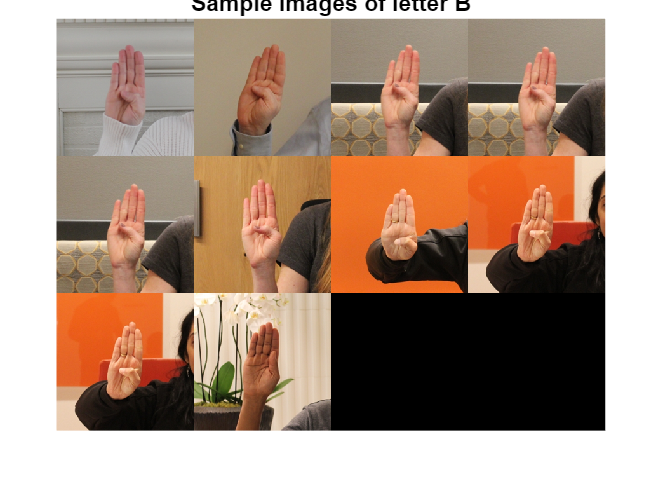


montage(imdsTest.Files(imdsTest.Labels == 'B'));
title('Sample images of letter B');

**Part 2: Model Training and Evaluation**

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:55        0.001                            3.6829
            1        1       00:00:56        0.001          3.4181                  
           50       17       00:20:38        0.001      0.00098156           0.54143
           90       30       00:36:56        0.001      7.4789e-05           0.48203
Training stopped: Max epochs completed


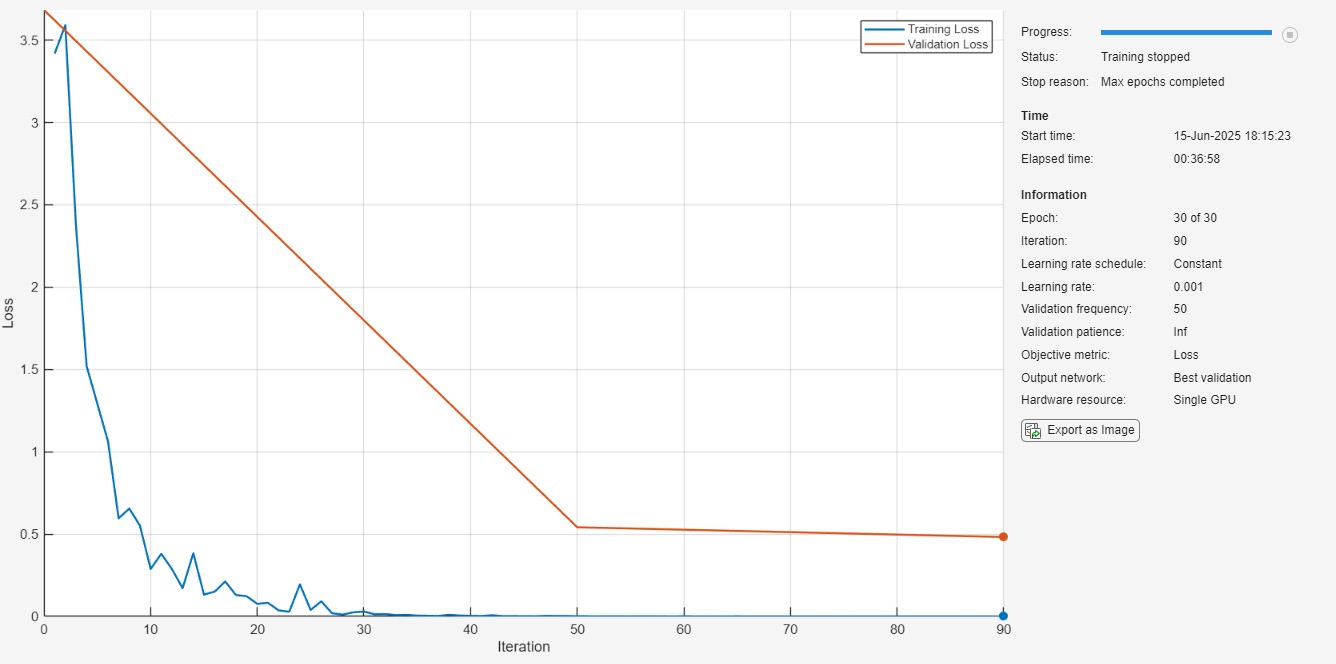


% Specify training options: Adam optimizer, validation data, GPU acceleration, etc.
opts = trainingOptions("adam", ...
    "ValidationData", augVal, ...
    "Plots", "training-progress", ...
    "Shuffle", "every-epoch", ...
    "ExecutionEnvironment", "gpu");

% Train the network with cross-entropy loss function
newNet = trainnet(augTrain, net, "crossentropy", opts);


% Predict on validation set, convert scores to class labels
predVal = minibatchpredict(newNet, augVal);
classes = categories(dsVal.Labels);
predValClass = scores2label(predVal, classes);

% Calculate and display validation accuracy
valAcc = nnz(dsVal.Labels == predValClass) / length(predValClass);
disp("Validation Accuracy: " + valAcc);

Validation Accuracy: 0.875



% Predict on test set and compute accuracy
predTest = minibatchpredict(newNet, augTest);
classes = categories(imdsTest.Labels);
predTestClass = scores2label(predTest, classes);

testAcc = nnz(imdsTest.Labels == predTestClass) / length(predTestClass);
disp("Test Accuracy: " + testAcc);

Test Accuracy: 0.9125


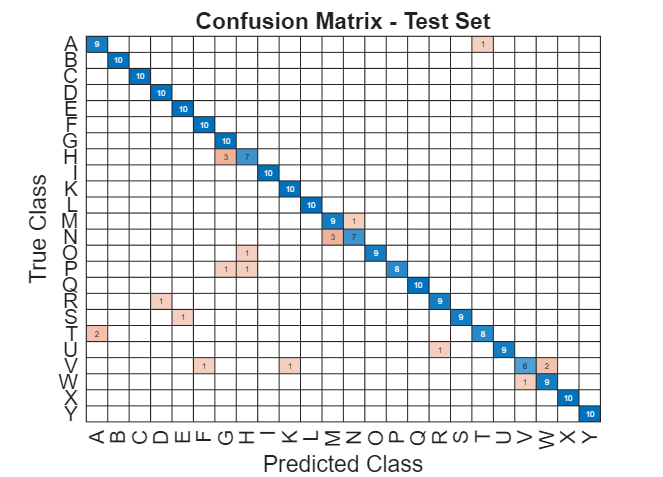


% Visualize confusion matrix for test predictions
confusionchart(imdsTest.Labels, predTestClass);
title("Confusion Matrix - Test Set");

**Part 3: Prediction on New, Unlabeled Images**


% Predict classes for unlabeled images
predUnlabeled = minibatchpredict(newNet, augUnlabeled);
predUnlabeledClass = scores2label(predUnlabeled, classes);

% Display predicted classes for the unlabeled dataset
disp("Predicted Classes for Unlabeled Images:");

Predicted Classes for Unlabeled Images:


disp(predUnlabeledClass);

     G 
     R 
     E 
     A 
     T 
     D 
     C 
     R 
     K 

